# Design and Train YOLOv2 in MATLAB 

## Step 1: Design YOLOv2 network layers

In this model we designed a custom YOLOv2 model layer by layer. The model starts by an input layer. Then the detection subnetwork contains a series of `Conv`, `Batch norm`, and `ReLu` layers, followed by the, [`yolov2TransformLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2transformlayer.html) and [`yolov2OutputLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2outputlayer.html) objects, respectively. [`yolov2TransformLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2transformlayer.html) transforms the raw CNN output into a form required to produce object detections. [`yolov2OutputLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2outputlayer.html) defines the anchor box parameters and implements the loss function used to train the detector.

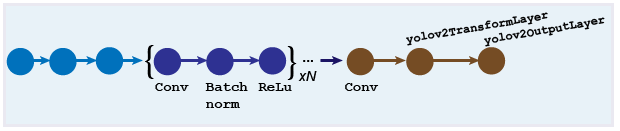

The` imageInputLayer` function is used to define the image input layer with minimum image size (128x128x3 used here). Depending on what you are trying to train different size can be better.

inputLayer = imageInputLayer([128 128 3],'Name','input','Normalization','none');

`Set the convolution layer filter size to [3 3]. `This size is common in CNN architectures. `FilterSize` defines the size (height & width) of the local regions to which the neurons connect in the input.

filterSize = [3 3];

For the middle layers we followed the basic approach of [YOLO9000](https://arxiv.org/pdf/1612.08242.pdf) paper and used a a repeated batch of [Convolution2dLayer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html?searchHighlight=Convolution2dLayer&s_tid=doc_srchtitle)`,`[Batch Normalization Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html?searchHighlight=batchnormalizationlayer&s_tid=doc_srchtitle)`,`[RelU Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html?searchHighlight=relu%20layer&s_tid=doc_srchtitle)` and `[Max Pooling Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html?s_tid=doc_ta). Similar to the other classification models like VGG model we doubled the no of channels (`filterSize`) after every pooling step. We used batch normalization to stabilize training, speed up convergence and regularize the model. 

middleLayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name','conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name','conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
    ];

## Step 2: Create layer graph for yolov2 network.

Combine the initial & middle layers and convert into a layer graph object in order to manipulate the layers

lgraph = layerGraph([inputLayer; middleLayers]);

Compute number of Classes based on Input data.

numClasses = size(trainingData,2)-1;

## Step 3: Define Anchor boxes

*Anchor boxes* are a set of predefined bounding boxes of a certain height and width. These boxes are defined to capture the scale and aspect ratio of specific object classes you want to detect and are typically chosen based on object sizes in your training datasets. You can define several anchor boxes, each for a different object size. The use of anchor boxes enables a network to detect multiple objects, objects of different scales, and overlapping objects. You can study in details about the [Basics of anchor boxes ](https://www.mathworks.com/help/vision/ug/anchor-box-basics.html)here. 

The anchor boxes is selected based on the scale and size of objects in the training data. You can [Estimate Anchor Boxes Using Clustering](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-using-clustering-for-deep-learning.html) to determine a good set of anchor boxes based on the training data. Using this procedure, the anchor boxes for the dataset are:

Anchors = [43 59
    18 22
    23 29
    84 109];

%Anchorboxes can be estimated from the anchorboxes file
Anchors2 = [
    48    79
    93    60
   104    42];

Anchors3 = [
    56    84
   107    67
    97    51];

Anchors416x416 = [
   326   187
   157   242
   181   298];


## Step 4: Assemble YOLOv2 network

The [yolov2Layers](https://www.mathworks.com/help/vision/ref/yolov2layers.html?s_tid=doc_ta) function creates a YOLO v2 network, which represents the network architecture for YOLO v2 object detector.

`'relu_4'` is the feature extraction layer , The features extracted from this layer are given as input to the YOLO v2 object detection subnetwork. You can specify any network layer except the fully connected layer as the feature layer.

!! change input size here if using different size for input layer !!

lgraph = yolov2Layers([128 128 3],numClasses,Anchors3,lgraph,'relu_4');

Visualize the `lgraph` using the `network analyzer app.`

analyzeNetwork(lgraph);

## Step 5: Train the Network

We train the model using adam and a learning rate of 0.001, we decided to change the mini batch size to 8. For our training we used 400 epochs, this was determined by trial and error to give the best results.

    options = trainingOptions('adam', ...
        'InitialLearnRate',0.001, ...
        'Verbose',true,'MiniBatchSize',8,'MaxEpochs',400,...
        'Shuffle','every-epoch','VerboseFrequency',25, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment','auto',Plots="training-progress");

Call the YOLOv2 training function - [trainYOLOv2ObjectDetector](https://www.mathworks.com/help/vision/ref/trainyolov2objectdetector.html?s_tid=doc_ta)

[detectorYolo2, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);    
save detectorYolo2

## Step 6: Detect with the detector

make a camera instance and try to detect objects on it.

camera = webcam(1);
h = figure;

while ishandle(h)
    im = snapshot(camera);
    
    %im = imresize(im,inputSize);
    [allBboxes,allScore,allLabels] = detect(detectorYolo2,im, 'Threshold', 0.6);
    [bboxes,score,labels] = selectStrongestBboxMulticlass(allBboxes,allScore,allLabels);
        im = insertObjectAnnotation(im,'Rectangle',bboxes,cellstr(labels),Fontsize=32);
        image(im)
    drawnow
end